# Overlay electrode positions and visual areas on a brain mesh 

% Repositories needed
%   vistasoft
%   ecogBasicCode 
%
% DH/BW/LMP Vistasoft Team, 2017


## Authorization

st = scitran('stanfordlabs')

## Configuration and Dependency Checking

project       = 'SOC ECoG (Hermes)';
session_label = 'ses-01';
subject_code  = 'sub-19';

st.toolbox('project',project,'file','toolboxes.json');
chdir(fullfile(ecogRootPath,'local'));
workDir = pwd;

## Query for and Download Required Data from Flywheel

% Get the electrode positions
electrodePositions = st.search('files',...
                               'project label',project,...
                               'session label',session_label,...
                               'file name','sub-19_loc.tsv');
fnameElectrodes = fullfile(workDir,'sub-19_loc.tsv');
st.get(electrodePositions{1},'destination',fnameElectrodes);

% Get the pial surface from the Analysis
lhPial = st.search('files in analysis',...
                   'project label', project,...
                   'session label',session_label,...
                   'file name','rt_sub000_lh.pial.obj');
fNamePial = fullfile(workDir,'lhPial.obj');
st.get(lhPial{1},'destination',fNamePial);

% Get orig anatomical image relating the T1 and FreeSurfer coordinates
orig = st.search('files',...
                 'project label', project,...
                 'session label',session_label,...
                 'acquisition label','anat',...
                 'file name','orig.mgz');
fNameOrig = fullfile(workDir,'orig.mgz');
st.get(orig{1},'destination',fNameOrig);

% Get Wang and Kastner color labels for the mesh
labels = st.search('files',...
                   'project label', project,...
                   'session label', session_label,...
                   'acquisition label','anat',...
                   'file name','lh.wang2015_atlas.mgz');
fNameLabel = fullfile(workDir,'lh.wang2015_atlas.mgz');
st.get(labels{1},'destination',fNameLabel);

## Compute the Transformation Matrix 

% From Freesurfer to the T1 data coord frame.
origData = MRIread(fNameOrig);
Torig    = origData.tkrvox2ras;
Norig    = origData.vox2ras;
freeSurfer2T1 = Norig/Torig; 

## Build the Brain Surface

% Read the pial surface
[vertex,face] = read_obj(fNamePial);

% convert vertices to original space
g.vertices = vertex';
g.faces = face';
g.mat = eye(4,4);
g = gifti(g);

% Convert the vertices into the T1 coordinate frame
vert_mat = double(([g.vertices ones(size(g.vertices,1),1)])');
vert_mat = freeSurfer2T1*vert_mat;
vert_mat(4,:) = [];
vert_mat = vert_mat';
g.vertices = vert_mat; 
clear vert_mat

## Render the Brain and Electrode Positions

ecog_RenderGifti(g)

% Set a good position for the viewer and the light 
ecog_ViewLight(270,0)

% Load and add electrode positions
ePositions = importdata(fnameElectrodes);
elecMatrix = ePositions.data(:,2:4);
ecog_Label(elecMatrix,10,20)

## Render the brain with colors and electrodes

surface_labels = MRIread(fNameLabel);
vert_label = surface_labels.vol(:);

cmap = 'lines';
% cmap = lines(max(vert_label));
Wang_ROI_Names = {...
    'V1v' 'V1d' 'V2v' 'V2d' 'V3v' 'V3d' 'hV4' 'VO1' 'VO2' 'PHC1' 'PHC2' ...
    'TO2' 'TO1' 'LO2' 'LO1' 'V3B' 'V3A' 'IPS0' 'IPS1' 'IPS2' 'IPS3' 'IPS4' ...
    'IPS5' 'SPL1' 'FEF'};

% Render the ROI labels on image
figure;
ecog_RenderGiftiLabels(g,vert_label,cmap,Wang_ROI_Names)
el_add(elecMatrix,'k',30)
el_add(elecMatrix,[.9 .9 .9],20)
saveas(gcf,fullfile(workDir,[subject_code, '_ElectrodePositionsAndLabels.png']));


## Upload Generated Image Back up to Flywheel Session 

% Query for the target
target = st.search('sessions',...
                   'project label', project,...
                   'subject code', subject_code);
% Build uplaod struct with the information needed to upload the result
upload.file = fullfile(workDir,[subject_code, '_ElectrodePositionsAndLabels.png']);
upload.containerType = 'sessions';
upload.id = target{1}.id;

% Do the upload
st.put('file', upload);

## View The uploaded file on Flywheel

st.browser(target{1}, 'tab', 'annotation');

## Use Code up on Flywheel to Render Movie of Brain

We can also make a movie of the electrodes using these few lines.  The movie file will be saved in vistasoft/local, and the file name will be:   wang2015_atlas_electrodes_movie.mp4

Number of files found:  1
API Key found for vistalab
42 projects found
*** Found toolbox ecogBasicCode
frame 10
frame 20
frame 30
frame 40
frame 50
frame 60
frame 70
frame 80
frame 90
frame 100
frame 110
frame 120
frame 130
frame 140
frame 150
frame 160
frame 170
frame 180


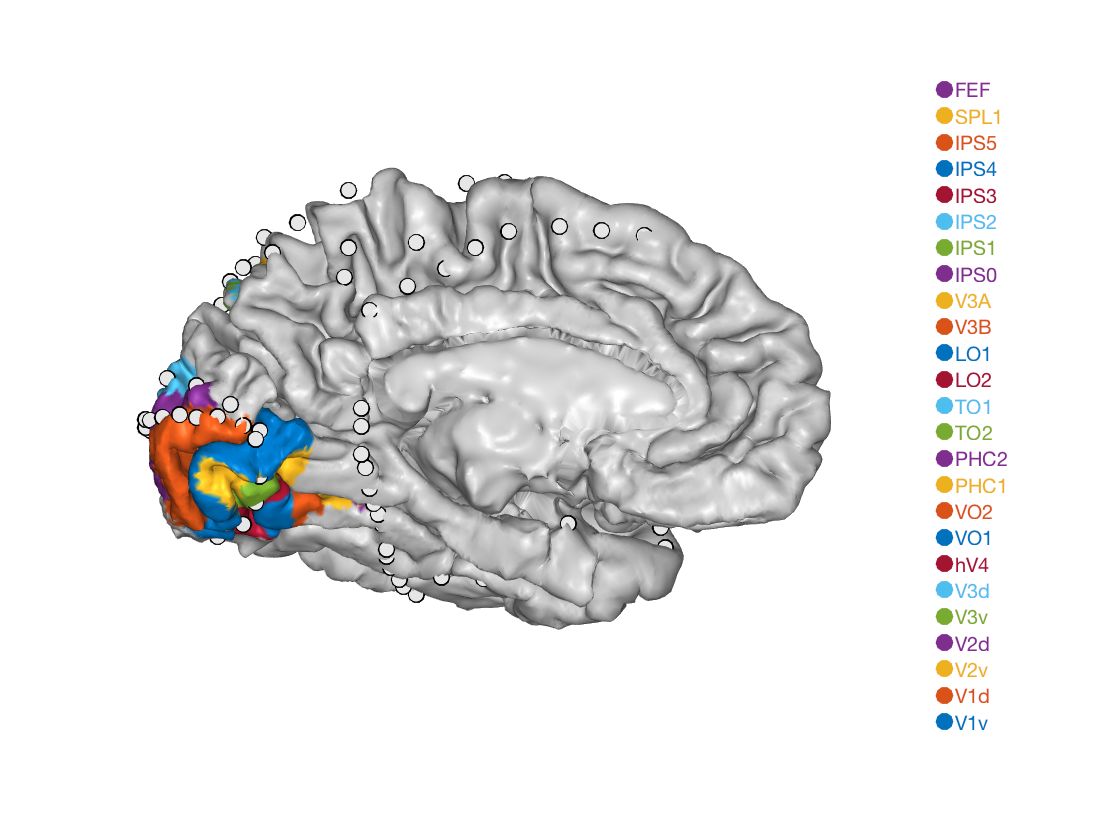

% This specifies the angles of brain rotation
st = scitran('stanfordlabs');
params.views = [-89:1:90; -10*ones(1,180)]';
st.runFunction('ecog_RenderElectrodesMovie.m','project','SOC ECoG (Hermes)',...
     'destination',fullfile(vistaRootPath,'local'),...
     'params',params);